## Question 2

Q2) In this question we are asked to implement a radix-3 fft function.

a) We first want to obtain a formula for a ${N=3}^n \;$point FFT. Let's start with 3N points:

$X\left\lbrack k\right\rbrack =\sum_{n=0}^{N-1} x\left\lbrack n\right\rbrack e^{-2\pi j\frac{\mathrm{nk}}{N}} \;\;\;\;\;\;X\left\lbrack 3r\right\rbrack$ split this into three partitions:


$$X\left\lbrack 3r\right\rbrack =\sum_{n=0}^{\frac{N}{3}-1} x\left\lbrack n\right\rbrack e^{-2\pi j\frac{\mathrm{n3r}}{N}} +\sum_{n=0}^{\frac{N}{3}-1} x\left\lbrack n+\frac{N}{3}\right\rbrack e^{-2\pi j\frac{\left(n+\frac{N}{3}\right)\mathrm{3r}}{N}} +\sum_{n=0}^{\frac{N}{3}-1} x\left\lbrack n+\frac{2N}{3}\right\rbrack e^{-2\pi j\frac{\left(n+\frac{2N}{3}\right)\mathrm{3r}}{N}}$$



$$X\left\lbrack 3r\right\rbrack =\sum_0^{\frac{N}{3}-1} e^{2\pi j\frac{\mathrm{nr}}{N/3}} \left(x\left\lbrack n\right\rbrack +x\left\lbrack n+\frac{N}{3}\right\rbrack +x\left\lbrack n+\frac{2N}{3}\right\rbrack \right)$$


similarly:


$$X\left\lbrack 3r+1\right\rbrack =\sum_0^{\frac{N}{3}-1} e^{2\pi j\frac{\mathrm{nr}}{N/3}} \left(x\left\lbrack n\right\rbrack +e^{2\pi j\frac{1}{3}} x\left\lbrack n+\frac{N}{3}\right\rbrack +e^{2\pi j\frac{2}{3}} x\left\lbrack n+\frac{2N}{3}\right\rbrack \right)$$



$$X\left\lbrack 3r+2\right\rbrack =\sum_0^{\frac{N}{3}-1} e^{2\pi j\frac{\mathrm{nr}}{N/3}} \left(x\left\lbrack n\right\rbrack +e^{2\pi j\frac{2}{3}} x\left\lbrack n+\frac{N}{3}\right\rbrack +e^{2\pi j\frac{4}{3}} x\left\lbrack n+\frac{2N}{3}\right\rbrack \right)$$
  

After this point, we implement a butterfly pattern similar to radix-2 DIF fft and obtain the function "ffft3n" which is available at the end of the question. The butterfly pattern is available in the next part:

b)

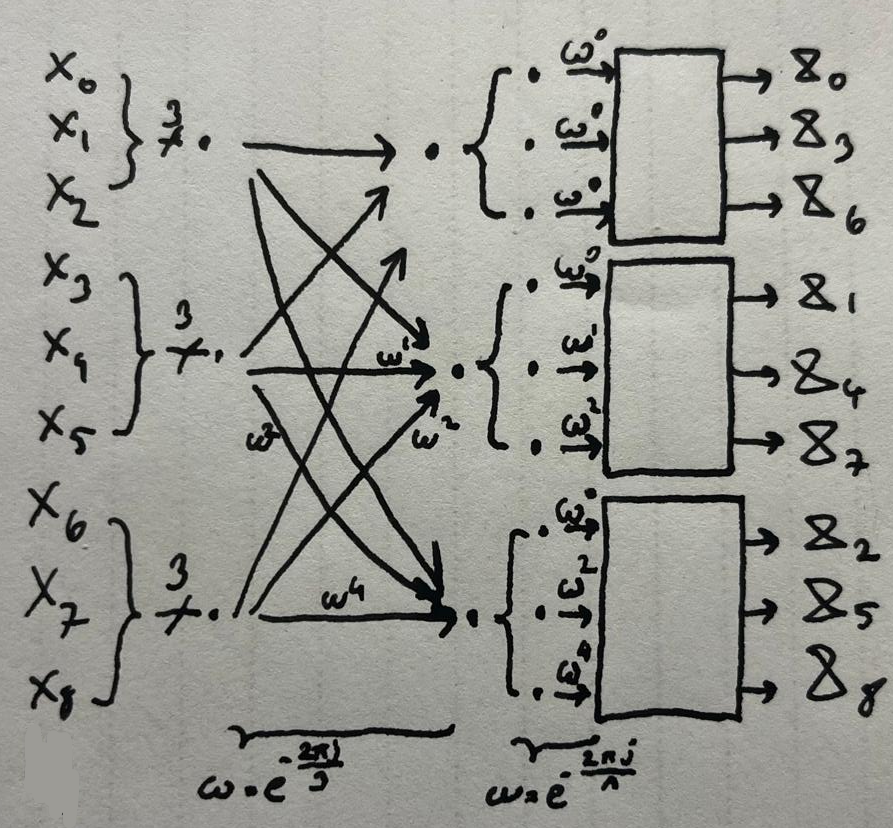

c) Generation of the 9 point random array and direct summation method.

rng(2,"twister")
N = 9;
real_part = randn(1,N);
imag_part = randn(1,N);
x = real_part + 1i*imag_part;

ns = linspace(0,N-1,N);
tic
dft_x = ns*0;
for i = 1:N
    dft_x = dft_x + x(i) * exp((i-1)*-2j*pi/N).^ns;
end
time_direct_summation_9 = toc;

d) Calculate the 9 point fft using our function and time it.

tic
x_ffft3n = ffft3n(x);
time_ffft3n_9 = toc;

e) Calculate the 9 point fft using MATLAB's fft and time it:

tic
x_fft = fft(x);
time_fft_9 = toc;

f) Check the equivalence of our methods from parts c,d,e.

disp(array2table([abs(sum(dft_x - x_fft)) abs(sum(x_ffft3n - dft_x)) abs(sum(x_ffft3n - x_fft))]))

       Var1          Var2          Var3   
    __________    __________    __________

    9.9511e-15    6.0755e-15    4.0107e-15



g) Check the efficencies of our methods.

Part_g = {'Direct Summation',time_direct_summation_9;'Radix-3 FFT',time_ffft3n_9;'MATLAB FFT',time_fft_9}

Part_g = 3×2 cell array
    {'Direct Summation'}    {[0.0046]}
    {'Radix-3 FFT'     }    {[0.0018]}
    {'MATLAB FFT'      }    {[0.0018]}


My radix-3 DIF FFT has the same speed as MATLAB's FFT which are both faster than the direct summation method. This aligned with our expectations and my FFT is also nicely optimised.

||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||||

    function X = ffft3n(x,n)
        arguments
            x (1,:) double
            n (1,1) double = length(x)
        end
        if isscalar(x)
            X = x;
        else
            twiddle3 = exp(-2j*pi/3);
            twiddle = exp(-2j*pi/n);
            x1p = x(1:end/3);
            x2p = x(end/3+1:end*2/3);
            x3p = x(end*2/3+1:end);
    
            x1 = x1p+x2p+x3p;
            x2 = x1p+x2p.*(twiddle3.^1)+x3p.*(twiddle3.^2);
            x3 = x1p+x2p.*(twiddle3.^2)+x3p.*(twiddle3.^4);
            
            X1 = ffft3n(x1);
            X2 = ffft3n(x2.*(twiddle.^[0:n/3-1]));
            X3 = ffft3n(x3.*(twiddle.^[0:2:2*n/3-2]));
    
            X = zeros([1,n]);
            for i = 1:length(X1)
                X(3*i-2) = X1(i);
                X(3*i-1) = X2(i);
                X(3*i)   = X3(i);
            end
        end
    end